# CAPÍTULO 11 - FLEXIÓN LONGITUDINAL-TRANSVERSAL Y ESTABILIDAD DE BARRAS

Comprueba los dos planos principales de una columna y representa su deformada espacial. La carga crítica global es la menor de ambas direcciones.

Dimensión: dos planos principales de flexión y deformada 3D. La carga crítica global comprueba ambas direcciones; no representa pandeo flexotorsional.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

I=[Iy Iz], o un escalar para una sección con igual inercia en ambos ejes. cargasLaterales tiene [posición FY FZ]; la longitud sigue X global. extremos puede ser "articulada_articulada", "empotrada_libre", "empotrada_empotrada" o "empotrada_articulada". P es compresión positiva.

L=2;E=210e9;I=[8e-8 12e-8];F=600e-6;
extremos="articulada_articulada";elementos=24;P=10000;
cargasLaterales=[.83 100 60];
limiteProporcional=200e6;

## 2. Dos planos de estabilidad


$$P_{cr}=\min\left(\frac{\pi^2EI_y}{(\mu L)^2},\frac{\pi^2EI_z}{(\mu L)^2}\right),\qquad (\mathbf{K}-P\mathbf{G})\mathbf{u}=\mathbf{f}$$


La flexión hacia Y utiliza Iz y la flexión hacia Z utiliza Iy. Para apoyos iguales, la dirección con menor inercia tiene la menor carga crítica. Si las inercias son iguales hay dos modos flexionales degenerados: cualquier combinación de ambas direcciones es posible.

resultado=rm_columna3d(L,E,I,elementos,extremos,P,cargasLaterales);
primero=rm_columna3d(L,E,I,elementos,extremos,0,cargasLaterales);
sigmaCritica=resultado.Pcritica/F;EulerAplicable=sigmaCritica<=limiteProporcional;
disp(table(["Flexion hacia Y";"Flexion hacia Z"], ...
    [resultado.planoY.Pcritica;resultado.planoZ.Pcritica]/1000, ...
    'VariableNames',{'Plano','Pcr_kN'}));

          Plano          Pcr_kN
    _________________    ______

    "Flexion hacia Y"    62.179
    "Flexion hacia Z"    41.452



disp(table(resultado.Pcritica/1000,resultado.margen,sigmaCritica/1e6,EulerAplicable, ...
    'VariableNames',{'Pcr_global_kN','Margen','sigmaCritica_MPa','Regimen_elastico_valido'}));

    Pcr_global_kN    Margen    sigmaCritica_MPa    Regimen_elastico_valido
    _____________    ______    ________________    _______________________

       41.452        4.1452         69.087                  true          



## 3. Modo, amplificación y deformada 3D

La amplitud del modo propio es arbitraria. La deformada bajo carga sí tiene unidades y se amplifica únicamente para dibujarla. La evaluación se detiene al alcanzar la primera carga crítica de cualquiera de los dos planos.

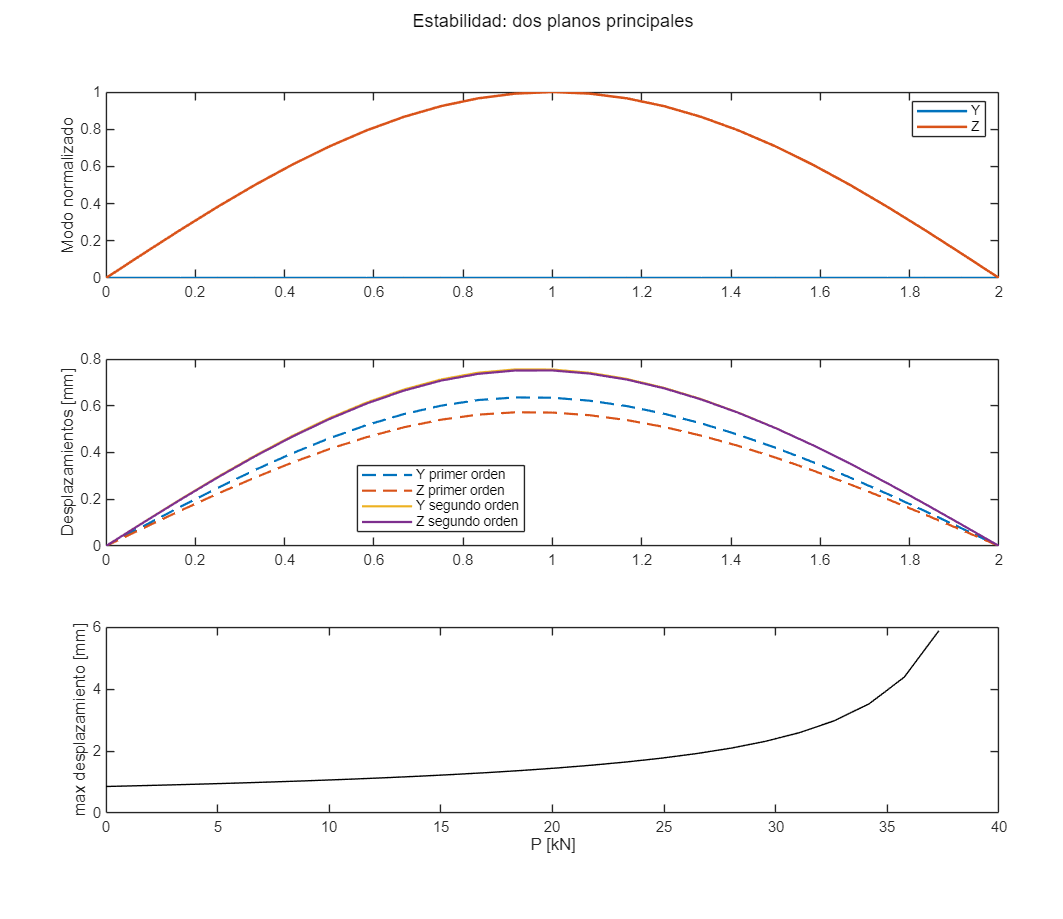

[figura,ejes]=rm_figura(3,'Estabilidad: dos planos principales');
plot(ejes(1),resultado.x,resultado.modo,'LineWidth',1.5);ylabel(ejes(1),'Modo normalizado');legend(ejes(1),{'Y','Z'});
plot(ejes(2),resultado.x,primero.u*1000,'--',resultado.x,resultado.u*1000,'LineWidth',1.3);
ylabel(ejes(2),'Desplazamientos [mm]');legend(ejes(2),{'Y primer orden','Z primer orden','Y segundo orden','Z segundo orden'},'Location','best');
pp=linspace(0,.9*resultado.Pcritica,25);vv=zeros(size(pp));
for j=1:numel(pp)
    a=rm_columna3d(L,E,I,elementos,extremos,pp(j),cargasLaterales);vv(j)=max(vecnorm(a.u,2,2))*1000;
end
plot(ejes(3),pp/1000,vv,'k-');xlabel(ejes(3),'P [kN]');ylabel(ejes(3),'max desplazamiento [mm]');

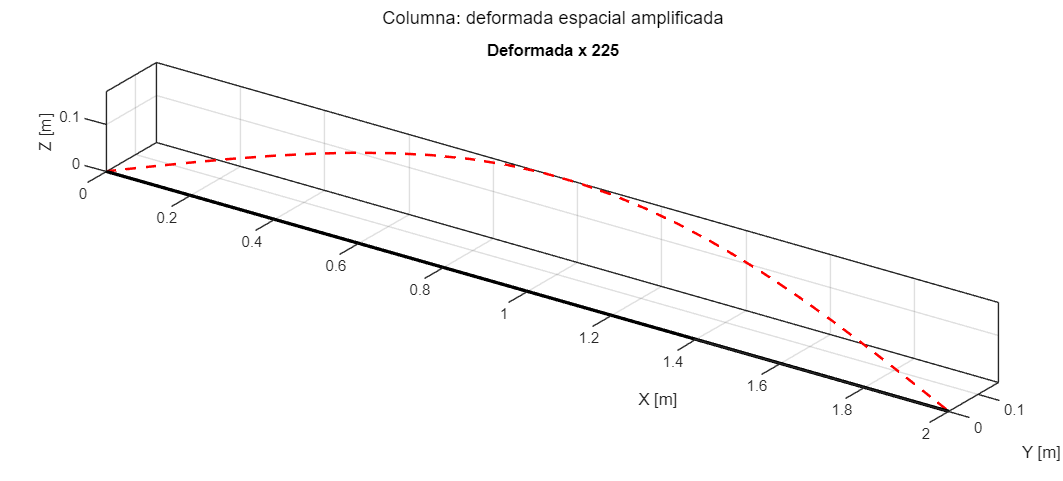

[figura,ejes]=rm_figura(1,'Columna: deformada espacial amplificada');hold(ejes(1),'on');
escala=.12*L/max(max(vecnorm(resultado.u,2,2)),realmin);
plot3(ejes(1),[0 L],[0 0],[0 0],'k-','LineWidth',2);
plot3(ejes(1),resultado.x,resultado.u(:,1)*escala,resultado.u(:,2)*escala,'r--','LineWidth',1.5);
view(ejes(1),35,24);axis(ejes(1),'equal');grid(ejes(1),'on');
xlabel(ejes(1),'X [m]');ylabel(ejes(1),'Y [m]');zlabel(ejes(1),'Z [m]');
title(ejes(1),sprintf('Deformada x %.3g',escala));

## Funciones utilizadas

rm_columna3d: resuelve los dos planos principales. Aquí elige la menor carga crítica y combina los desplazamientos espaciales.

vecnorm: calcula una norma para cada fila o columna. Aquí obtiene la magnitud combinada de los desplazamientos Y y Z.

plot3: dibuja líneas con tres coordenadas. Aquí muestra el eje original y la deformada espacial.

eig: resuelve un problema de valores propios. Aquí la rutina obtiene la carga crítica de cada plano.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Columna prismática de ejes principales, mismo tipo de apoyo en ambos planos, compresión conservativa constante y flexión de segundo orden linealizada. No incluye pandeo por torsión, flexotorsión, pospandeo ni plastificación. Las cargas interiores se aplican mediante funciones de forma; refina la malla para comprobar convergencia.

Conexión con lo anterior: Reutiliza las inercias del capítulo 3 y la energía de flexión del 7. La comprobación se realiza en ambas direcciones, no solo en la dirección de la fuerza lateral.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 11: calculo completado.');

Capitulo 11: calculo completado.
